% Filtro IIR Chebyshev - Pasa bajo
% filipuzzi, fernando rafael
% fecha: 20221024
% matlab2021b

close all; clear all; clc;
digits(300);
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

**Filtro - IIR - Chebyshev - Diseño del filtro Pasa Bajo**

**Parámetros de diseño**

fm=22418;             % Hz,  Frecuencia de Muestreo
fMAX=fm/2;
                              fc=1000;
fp=950 ;                        fs=1150 ;              
Ap=0.1 ;                         As=15 ;     
                        

**Diseño del filtro**

- Transformación de las caracteristicas de frecuencia de paso bajo a paso bajo normalizado.

Fc=fc/fp;
Fp=fp/fp;
Fs=fs/fp;

- Cálculo del Orden del filtro:

%N=mi_butter_orden_lp(Fc, Ap, Fs, As)
[N,e]=mi_cheb1ord(Fc, Fs, Ap, As)

N =      8


e =      1.526204189509192e-01


- Función de transferencia y respuesta en frecuencia.

[BS,AS]=mi_cheby1(N,e);
sysS=tf(BS,AS)

sysS =
 
                                               0.03441
  -------------------------------------------------------------------------------------------------
  s^8 + 1.597 s^7 + 3.081 s^6 + 3.058 s^5 + 2.787 s^4 + 1.673 s^3 + 0.7851 s^2 + 0.2283 s + 0.03441
 
Continuous-time transfer function.



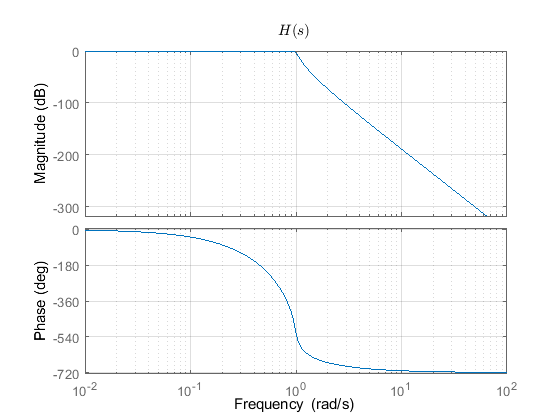

fig0=figure; bode(sysS); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;...
saveas(fig0,'output/stm32_iir_lp_chebyshev_0','jpg');

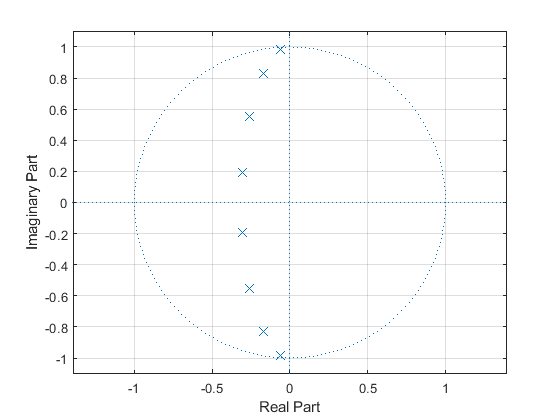

fig1=figure; Np=max(length(BS),length(AS)); 
zplane( [zeros(1, Np- length(BS)) BS], [ zeros(1, Np- length(AS)) AS] );...
grid on; saveas(fig1,'output/stm32_iir_lp_chebyshev_1','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(BS,s)/poly2sym(AS,s))];
save_ecu('output/stm32_iir_lp_chebyshev_ecu_SM.tex', ecu_latex);

- Transformación en frecuencia de paso bajo normalizado a paso bajo

[Bs, As] = lp2lp(BS, AS, 2*pi*fp);
syss=tf(Bs,As)

syss =
 
                                                          
                                                  5.546e28
                                                          
  --------------------------------------------------------------------------------------------------------
                                                                                                          
  s^8 + 9534 s^7 + 1.098e08 s^6 + 6.504e11 s^5 + 3.538e15 s^4 + 1.267e19 s^3 + 3.551e22 s^2 + 6.164e25 s  
                                                                                                          
                                                                                                + 5.546e28
                                                                                                          
 
Continuous-time transfer function.



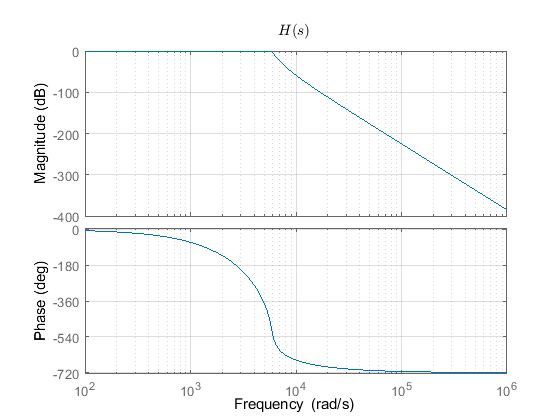

fig2=figure; bode(syss); ...
title(sprintf('$$%s$$', 'H(s)'), 'Interpreter','latex'); grid on;   ...
saveas(fig2,'output/stm32_iir_lp_chebyshev_2','jpg');

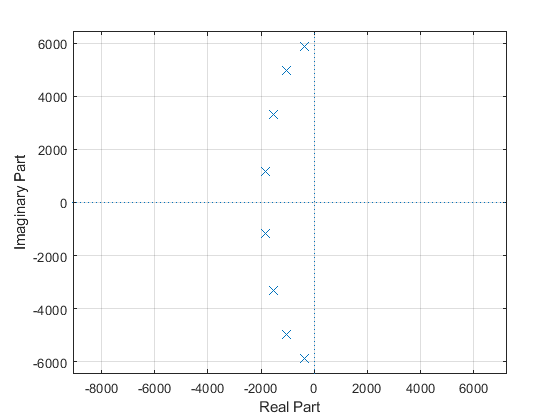

fig3=figure; Np=max(length(Bs),length(As));
zplane( [zeros(1, Np- length(Bs)) Bs ], [ zeros(1, Np- length(As)) As ] ); ...
grid on; saveas(fig3,'output/stm32_iir_lp_chebyshev_3','jpg');

syms s; ecu_latex = ['H(s)=', latex(poly2sym(Bs,s)/poly2sym(As,s))];
save_ecu('output/stm32_iir_lp_chebyshev_ecu_s.tex', ecu_latex);

**Transformación bilinear - matlab.**

mapeo="bilineal(matlab)";

switch mapeo
    case "integración"
        [Bz, Az]=mi_integral(Bs, As, fm);
    case "invariante al impulso"
        [Bz, Az]=mi_impinvar(Bs, As, fm);
    case "invariante(matlab)"
        [Bz, Az]=impinvar(Bs, As, fm);
    case "bilineal"
        [Bz, Az]=mi_bilinear(Bs, As, fm);        
     %   [r,p,k]=residue(Bs,As)
      %  [Bz,Az]=mi_bilinear_pk(r,p,fm)
    case "bilineal(matlab)"
        [Bz, Az]=bilinear(Bs, As, fm);        %,fp
end
Bz=Bz/Az(1);
Az=Az/Az(1);
sysz=tf(Bz,Az,1/fm,'Variable','z^-1')

sysz =
 
                                                                                                          
  2.663e-09 + 2.13e-08 z^-1 + 7.455e-08 z^-2 + 1.491e-07 z^-3 + 1.864e-07 z^-4 + 1.491e-07 z^-5           
                                                                                                          
                                                         + 7.455e-08 z^-6 + 2.13e-08 z^-7 + 2.663e-09 z^-8
                                                                                                          
  ---------------------------------------------------------------------------------------------------------
                                                                                                           
  1 - 7.455 z^-1 + 24.44 z^-2 - 46.04 z^-3 + 54.46 z^-4 - 41.44 z^-5 + 19.8 z^-6 - 5.432 z^-7 + 0.6551 z^-8
                                                                                                           
                        

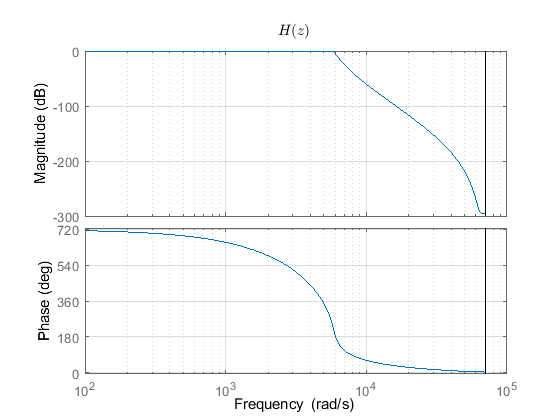

syms z; fig4=figure; bode(sysz); grid on;...
title(sprintf('$$%s$$', 'H(z)'), 'Interpreter','latex');    ...
saveas(fig4, 'output/stm32_iir_lp_butterworth_4', 'jpg');

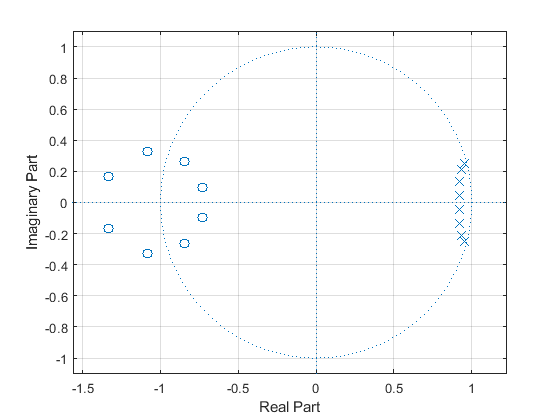

fig5=figure; Np=max( length(Bz), length(Az) );
zplane( [  zeros(1, Np- length(Bz)) Bz], [ zeros(1, Np- length(Az)) Az ] );...
grid on; saveas(fig5,'output/stm32_iir_lp_chebyshev_5','jpg');

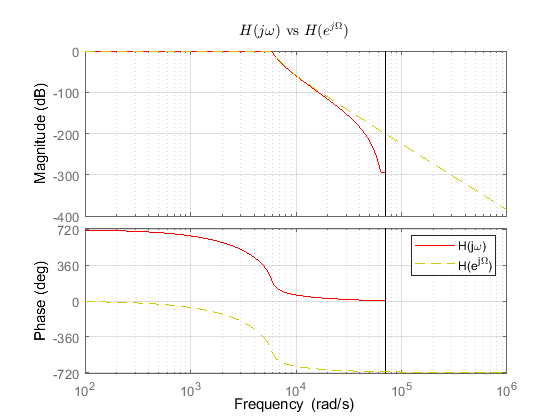

ecu_latex = ['H(z)=', latex(poly2sym(Bz,z)/poly2sym(Az,z))];
save_ecu('output/stm32_iir_lp_chebyshev_ecu_z.tex', ecu_latex);

syms z; fig6=figure; bode(sysz,'r',syss,'y--'); grid on;...
title(sprintf('$$%s$$', 'H(j\omega)\mbox{ vs }H(e^{j\Omega})'), 'Interpreter','latex');    ...    
legend( sprintf('%s', 'H(j\omega)'), sprintf('%s', 'H(e^{j\Omega})'));  
saveas(fig6,'output/stm32_iir_lp_chebyshev_6','jpg');

**Generación de la linea de código para el micrcontrolador - **vector de coeficientes

PRECISION_STM32=8;
stm32_coef=to_stm32(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Chebyshev -  Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_chebyshev_stm32_coef.txt', stm32_coef);...
fprintf('%s\n',stm32_coef) 

//Filtro IIR - Chebyshev -  Pasa Bajo - bilineal(matlab) 
//Orden: 8
//Frecuencia de Muestreo: 22418 (Hz)
#define ORDEN 8
double coef_x[]= {0.00000000,0.00000002,0.00000007,0.00000015,0.00000019, 
			0.00000015,0.00000007,0.00000002,0.00000000};
double coef_y[]= {-1.00000000,7.45524989,-24.44480967,46.03641080,-54.45992407, 
			41.43552867,-19.79953573,5.43221684,-0.65513740};


**Generación de la linea para inicializar el callback de simulink**

simulink_coef=to_simulink(Bz, Az, N, fm, PRECISION_STM32, 'IIR - Chebyshev - Pasa Bajo', mapeo); ...
saveImplementacion('output/stm32_iir_lp_chebyshev_simulink_coef.txt', simulink_coef); ...
fprintf('%s\n',simulink_coef) 

	%Filtro IIR - Chebyshev - Pasa Bajo - bilineal(matlab) 
	%Orden: 8
	%Frecuencia de Muestreo: 22418 (Hz)
	Fm=22418;
	ORDEN=8;
	coef_x= [2.6625652e-09,2.1300518e-08,7.4551842e-08,1.4910359e-07,1.8637965e-07, ...
			1.4910356e-07,7.4551874e-08,2.1300505e-08,2.6625673e-09];
	coef_y= [-1,7.4552499,-24.44481,46.036411,-54.459924, ...
			41.435529,-19.799536,5.4322168,-0.6551374];


save('output/stm32_iir_lp_chebyshev.mat');